# RESNET TEST LIVESCRIPT

## Clear Input Data Folders and recreate

clear
% Specify the folder where the files live.
myFolderBlanks = "InputData/BlanksFrames";
% Check to make sure that folder actually exists.  Warn user if it doesn't.
if isfolder(myFolderBlanks)
    % Get a list of all files in the folder with the desired file name pattern.
    filePattern = fullfile(myFolderBlanks, '*.png'); % Change to whatever pattern you need.
    theFiles = dir(filePattern);
    for k = 1 : length(theFiles)
      baseFileName = theFiles(k).name;
      fullFileName = fullfile(myFolderBlanks, baseFileName);
      delete(fullFileName);
    end
end

myFolderDots = "InputData/DotsFrames";
% Check to make sure that folder actually exists.  Warn user if it doesn't.
if isfolder(myFolderDots)
    % Get a list of all files in the folder with the desired file name pattern.
    filePattern = fullfile(myFolderDots, '*.png'); % Change to whatever pattern you need.
    theFiles = dir(filePattern);
    for k = 1 : length(theFiles)
      baseFileName = theFiles(k).name;
      fullFileName = fullfile(myFolderDots, baseFileName);
      delete(fullFileName);
    end
end

myFolderPlanes = "InputData/PlanesFrames";
% Check to make sure that folder actually exists.  Warn user if it doesn't.
if isfolder(myFolderPlanes)
    % Get a list of all files in the folder with the desired file name pattern.
    filePattern = fullfile(myFolderPlanes, '*.png'); % Change to whatever pattern you need.
    theFiles = dir(filePattern);
    for k = 1 : length(theFiles)
      baseFileName = theFiles(k).name;
      fullFileName = fullfile(myFolderPlanes, baseFileName);
      delete(fullFileName);
    end
end

myFolderTanks = "InputData/TanksFrames";
% Check to make sure that folder actually exists.  Warn user if it doesn't.
if isfolder(myFolderTanks)
    % Get a list of all files in the folder with the desired file name pattern.
    filePattern = fullfile(myFolderTanks, '*.png'); % Change to whatever pattern you need.
    theFiles = dir(filePattern);
    for k = 1 : length(theFiles)
      baseFileName = theFiles(k).name;
      fullFileName = fullfile(myFolderTanks, baseFileName);
      delete(fullFileName);
    end
end

## Read in and format data to RGB image


load("SyntheticDatasets\SyntheticData07Feb2024091156\CompleteDataset.mat"); % Select dataset to be used

dataset = RAWDATA;
if isfolder(myFolderBlanks)
    rmdir("InputData\BlanksFrames")
end
if isfolder(myFolderDots)
    rmdir("InputData\DotsFrames");
end
if isfolder(myFolderTanks)
    rmdir("InputData\TanksFrames");
end
if isfolder(myFolderPlanes)
    rmdir("InputData\PlanesFrames");
end
if isfolder("InputData\");
    rmdir("InputData\");
end
dataReal = real(dataset);
dataImag = imag(dataset);
dataPhase = magnitude(dataReal, dataImag);

[xSize,ySize,zSize] = size(dataset);

imageDataset = {};
dataImage = [];
filename = "InputImage"

filename = "InputImage"

filecount = 0;


DataType = 4; % 1 = dots, 2 = plane, 3 = tank, 4 = multiclass

% imds = imageDatastore('InputData', ...
%     'IncludeSubfolders',true, ...
%     'LabelSource','foldernames'); 
% [imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);


if DataType == 1

    dotsFolder = "InputData/DotsFrames/";
    blanksFolder = "InputData/BlanksFrames/";
    addpath("InputData");
    mkdir(dotsFolder);
    mkdir(blanksFolder);
    addpath(dotsFolder);
    addpath(blanksFolder);

end


if DataType == 4

    dotsFolder = "InputData/DotsFrames/";
    blanksFolder = "InputData/BlanksFrames/";
    planesFolder = "InputData/PlanesFrames/";
    tanksFolder = "InputData/TanksFrames/";
    addpath("InputData");
    mkdir(dotsFolder);
    mkdir(blanksFolder);
    mkdir(planesFolder);
    mkdir(tanksFolder);
    addpath(dotsFolder);
    addpath(blanksFolder);
    addpath(planesFolder);
    addpath(tanksFolder);

end


%% Read in synthetic data and format as a 3d image (RGB)

for i = 1:zSize
    dataImage(:,:,1) = dataReal(:,:,i);
    dataImage(:,:,2) = dataImag(:,:,i);
    dataImage(:,:,3) = dataPhase(:,:,i);
    %imageDataset(i) = {dataImage};
    filecount = string(i);
    indFilename = "InputData/" + filename + filecount + ".png";
    imwrite(dataImage, indFilename);

    if targetsInFrame(i) == 1
        movefile(indFilename, dotsFolder);
    elseif targetsInFrame(i) == 0
        movefile(indFilename, blanksFolder);
    elseif targetsInFrame(i) == 2
        movefile(indFilename, planesFolder);
    elseif targetsInFrame(i) == 3
        movefile(indFilename, tanksFolder);
    end
end


save("ImageDataset.mat", "imageDataset");

%imds = imageDatastore("ImageDataset.mat");
%[imdsTrain, imdsValidation] = splitEachLabel(imds,0.7);


## Create Image Data Store

imds = imageDatastore('InputData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);


## CNN Implementation

net = resnet18;
%net = googlenet;
inputSize = net.Layers(1).InputSize;

lgraph = layerGraph(net);

[learnableLayer,classLayer] = findLayersToReplace(lgraph);



## Replace Final Layers

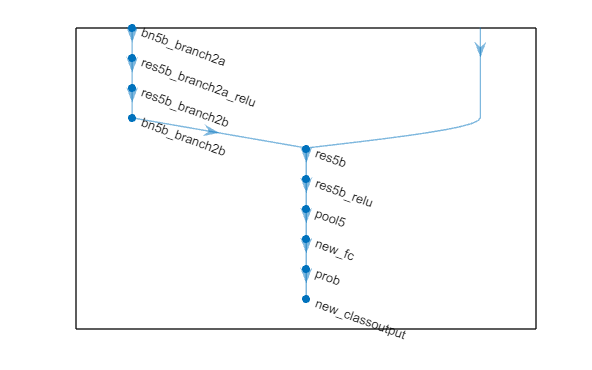



numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers



layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);


## Train Network

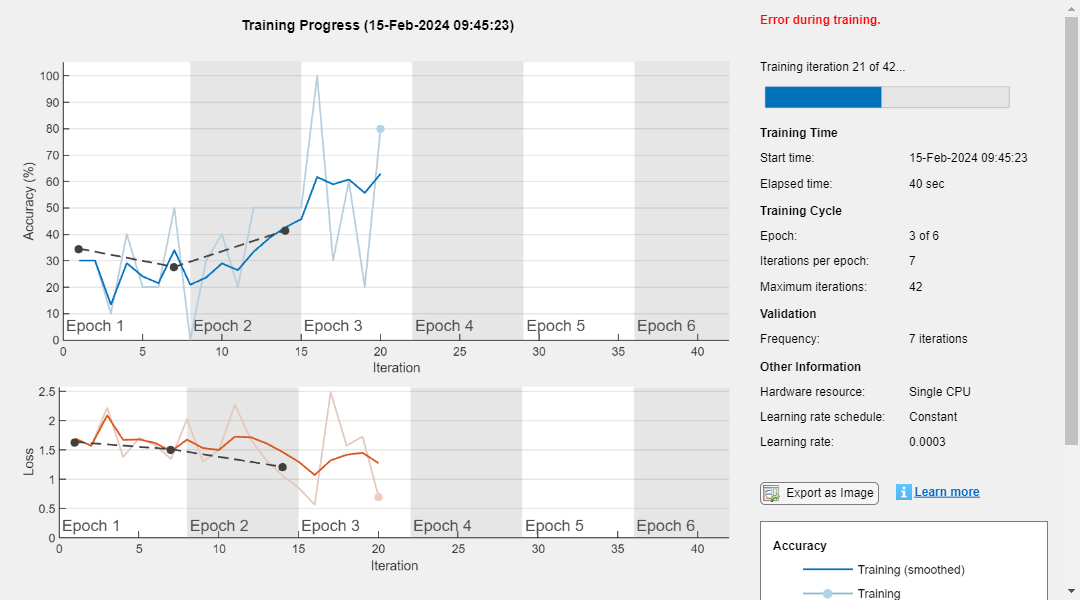

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);


miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');


net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels);


idx = randperm(numel(imdsValidation.Files),20);
figure
for i = 1:20
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end


## Magnitude Function

function magData = magnitude(realData, ImagData)
    
    magData = ((realData).^2+(ImagData).^2).^0.5;

end